## How does a phone know its absolute orientation?

        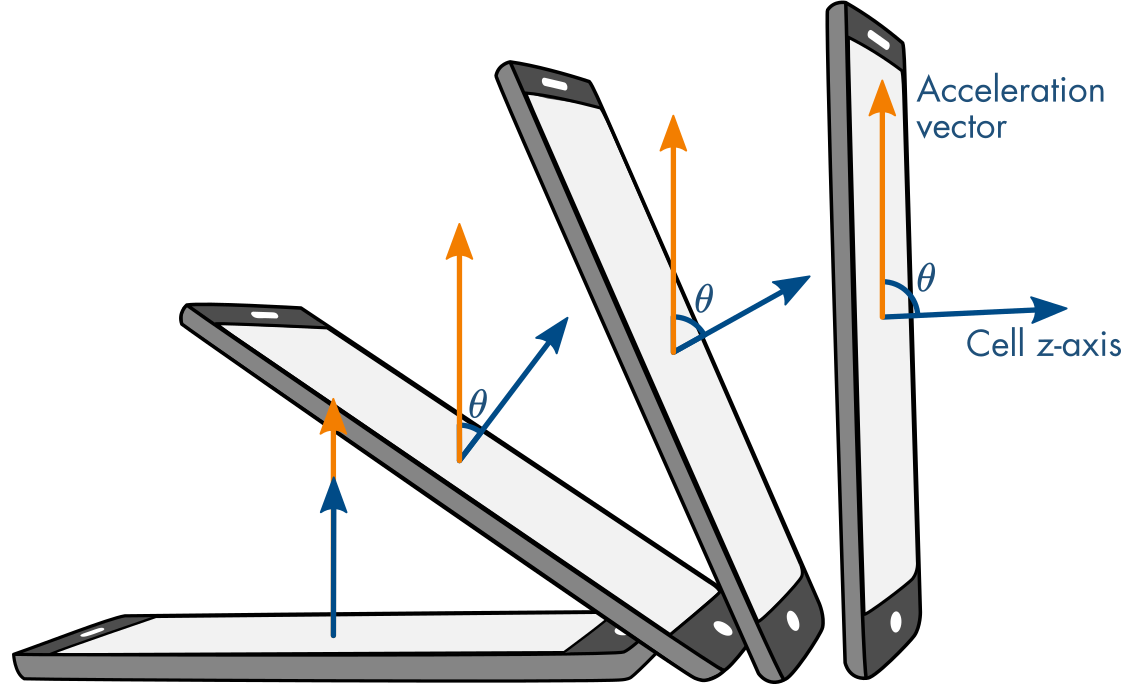

You can measure the pitch of a cell phone using accelerometer readings. However, an accelerometer is insufficient to identify the absolute orientation of the phone. That's because the acceleration vector points straight up (away from the center of the earth) and offers no information about the compass heading of the phone. So how do you determine the heading the of the phone relative to a known direction, like north?

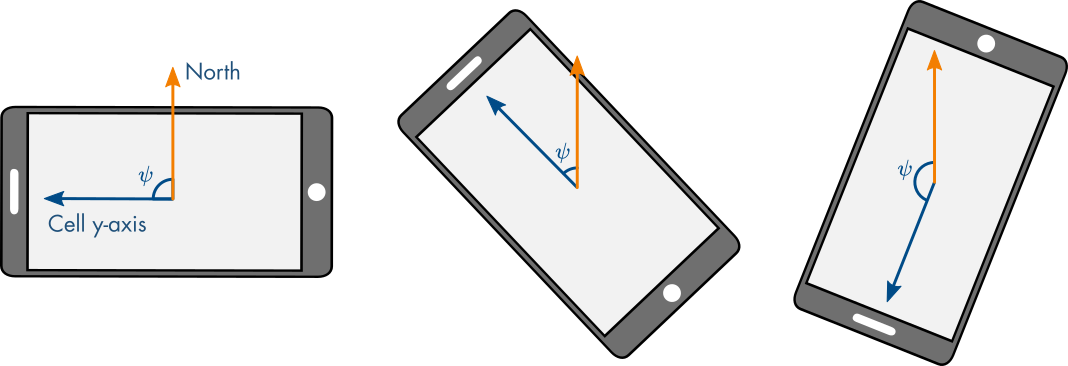

*Cell phones lying flat. The yaw angle *$\psi$* gives the bearing relative to north.*

The answer is the magnetometer, a device in your phone that measures the magnetic field of the Earth. The magnetometer acts as a compass, providing a vector reading that points in the direction of the Earth's magnetic field. By combining the accelerometer reading and the magnetometer reading, you can fully characterize the absolute orientation of the phone. But in order to combine the readings, you need to know the mathematics used to combine vectors.

# Vector Arithmetic

  **Pro-tip**: This live script is meant to be used with the code hidden. Select the `VIEW` tab and switch to `Hide Code`.

 Your answers should be accurate to at least 3 decimal places. If they are not, they will be marked incorrect.

## 1. Addition and subtraction

Adding vectors is as simple as adding their corresponding components. In three dimensions:

    
$$\mathbf{u} + \mathbf{v} = [ u_1 + v_1, u_2 + v_2, u_3 + v_3]$$
 

Subtraction works similarly.

** Exercise. **Add and subtract $\mathbf
{u}
 = [1,3,12]$,  $\mathbf{v}
 = [3, -6,0]$.

% Write the answer to u + v
checkAddition([0 0 0]); % default: [0 0 0]
% Write the answer to u - v
checkSubtraction([0 0 0]); % default: [0 0 0]

  **Reflect**

- For four-dimensional vectors, what would the formula be? 

- For n-dimensional vectors (e.g. $\mathbf{v} = [ v_1, v_2, \ldots, v_n]$), what would the formula be? 

Adding two vectors $\mathbf{u}$ and $\mathbf{v}$ yields a new vector $\mathbf{w} = \mathbf{u} + \mathbf{v}$. This new vector is called the **resultant** and can be visualized by connecting the tail of the first vector to the tip of the second vector. 

u = [0,2]; % default: u = [1,3]
v = [2,2]; % default: v = [2, 2]

% resultant vector
w = u+v; % default: u + v
plotNegV = false;

figure("position",[1 1 350 350])
hold on 
setup2DVectorPlot([-5 5 -5 5])
plotVector2D([0 0],u,"\mathbf{u}",1)
plotVector2D(u,v,"\mathbf{v}",1)
plotVector2D([0 0],w,"\mathbf{w}",-2)
if(plotNegV)
    plotVector2D(u,-v,"\mathbf{-v}",1)
end
hold off

  **Try**

- Change the components of $\mathbf{u}$ and $\mathbf{v}$. In each case, the two vectors connected end-to-end will terminate at the same position as their sum $\mathbf{w}$.

- Adjust the edit field for $\mathbf{w}$ so that it is the difference of the two vectors: $\mathbf{w} = \mathbf{u} - \mathbf{v}$.

- Add the graph of $-\mathbf{v}$ by clicking the check box.

### **Acceleration of a sliding cell phone**

  **Task. **Take accelerometer readings from your cell phone as indicated below or use the first two readings the attached video, [magnetometerReadings.mp4](matlab: winopen magnetometerReadings.mp4). Note that the link will only work if the file is in the MATLAB Path.

- Lay the cell phone flat and take a reading, $\mathbf{a}$. 

- Rapidly slide the phone across the surface and take another reading, $\mathbf{b}$. The acceleration values will change rapidly so simply pick the most extreme values (the exact value is unimportant).

            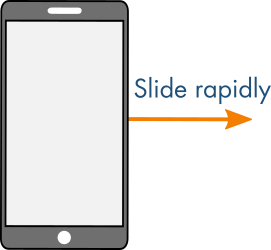

% Record your accelerometer values below 
a = [0 0 0]; % Default: [0 0 0] 
b = [0 0 0]; % Default: [0 0 0] 

** Exercise. **Subtract $\mathbf{a}$ from $\mathbf{b}$ and record the result in $\mathbf{c}$.

c = [0 0 0]; % Default: [0 0 0] 
gradeC(a, b, c)

% Graph the accelerometer vector
axisLims = [-10 10];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],a,"\mathbf{a}",-3)
plotVector3D([0 0 0],b,"\mathbf{b}",-3)
plotVector3D(a,c,"\mathbf{c}",-3)
hold off
view([150 25])

  **Reflect**

- The vector $\mathbf{b}$ combines two physical accelerations, $\mathbf{a}$ and $\mathbf{c}$. What are the real-life meanings of $\mathbf{a}$ and $\mathbf{c}$?

## 2. Scalar multiplication

Multiplying a vector by a scalar is as simple as multiplying every element of the vector by the scalar. The size of the vector doesn't matter, so this is true for a vector with N-dimensions (where N is an integer value such as 3).

    
$$a\mathbf{u} = [a u_1, a u_2, \ldots, a u_N ]$$
 

** Exercise. **Compute the scalar product $a \mathbf{u}$ of $a = \frac{1}{2}$ and $\mathbf{u} = [1, 4, -4]$.

checkScalarMult([0 0 0]) % Default: [0 0 0]

  **Reflect**

- What direction will $a\mathbf{u}$ point relative to $\mathbf{u}$?

- What will the magnitude of $a\mathbf{u}$ be relative to $\mathbf{u}$?

  **Try. **Click the checkbox below to graph $a\mathbf{u}$. Does it match your expectations?

% Define the vector
u = [1 4 -4];
a = 0.5;
plotau = false;

% Plot the vector
axisLims = [-5 5];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],u,"\mathbf{u}",-1)
if(plotau)
    plotVector3D([0 0 0],a*u,"a \mathbf{u}",1)
end
hold off
view([110 10])

  **Reflect**

- If $a = -2%$, what will the direction and magnitude of $a\mathbf{u}$ be relative to $\mathbf{u}$? Check your answer by adjusting the value of $a$ above.

-  Graphically it appears that $\Vert a\mathbf{u}\Vert = |a| \Vert \mathbf{u} \Vert
$. Compute the magnitude of an arbitrary 3D vector $a\mathbf{u} = [au_1, au_2, au_3]$ to show that this is indeed the case.

## 3. Dot product 

### Algebraic definition

The dot product of two N-dimensional vectors (aptly denoted "$\cdot$" ) is the sum of their element-wise product, i.e.,


$$\mathbf{u} \cdot \mathbf{v} = \sum_i u_i v_i = u_1 v_1 +  u_2 v_2 + \ldots + u_n v_n$$


** Exercise.  **Compute the dot product of $\mathbf{u} = [1, 3, 6]$ and $\mathbf{v} = [1, 0, 2]$.

checkDotProduct(0) % Default: 0

  **Reflect**

- Show that the dot product of a vector with itself is the square of the magnitude: $\mathbf{u} \cdot \mathbf{u} = \Vert \mathbf{u} \Vert^2$ in 3D ($\mathbf{u} = [u_1, u_2, u_3]$) by evaluating and simplifying $\mathbf{u} \cdot \mathbf{u}$.

- Is the dot product commutative (i.e., is $\mathbf{u} \cdot \mathbf{v} = \mathbf{v} \cdot \mathbf{u}$)? If so, prove it. If not, give a counterexample.

### Geometric definition

The dot product can be alternatively defined by

    
$$\mathbf{u} \cdot \mathbf{v} =\Vert \mathbf{u} \Vert  \Vert \mathbf{v} \Vert \cos \theta$$
 

where $\theta$ is the angle between $\mathbf{u}$ and $\mathbf{v}$.

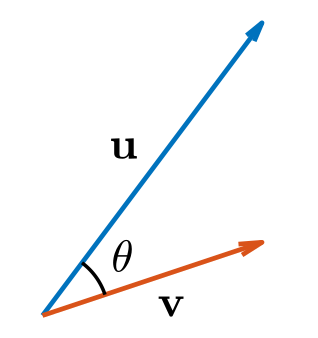

** Exercise. **Use the geometric definition to compute the dot product of the vectors $\mathbf{u} = [2,2]$ and $\mathbf{v} = [0, 2]$. The angle between $\mathbf{u}$ and $\mathbf{v}$ is 45$^\circ$.

checkGeometricDot(0) % Default: 0

  **Try**

- Recompute the dot product using the algebraic definition.

- [Challenge problem] Show that the two definitions are equivalent using two geometric laws:

- The parallelogram law in terms of vectors: $2 \Vert \mathbf{u} \Vert^2 + 2 \Vert \mathbf{v} \Vert^2 = \Vert \mathbf{u} + \mathbf{v} \Vert^2 + \Vert \mathbf{u} - \mathbf{v} \Vert^2$

- The law of cosines: 

                  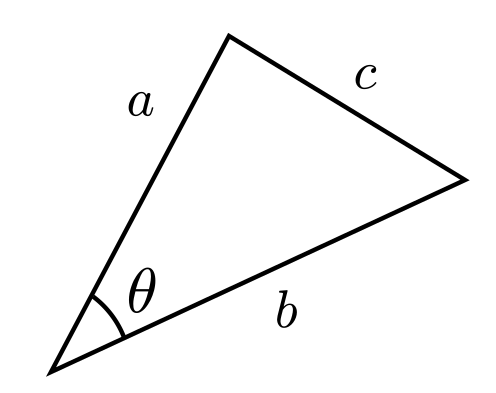

                
$$c^2 = a^2 + b^2 - 2ab \cos \theta$$


**Hint.** Draw a diagram with $\mathbf{u}$ and $\mathbf{v}$ that also has a third vector $\mathbf{w$ that connects $\mathbf{u}$ and $\mathbf{v}$.

### Angle between two 3D vectors

It seems like the geometric definition of the dot product is more difficult to compute. So how is it useful? In general, this definition is not used to compute the dot product. Instead, the formula is inverted, and used to compute the angle between the vectors.

** Exercise.** Solve for $\theta$ in the geometric definition of the dot product. Then use the result to compute the angle between the vectors $\mathbf{u} = [-1, 3, 2]$ and $\mathbf{v} = [2,4, -1]$. 

Ensure that your answer is accurate to at least four decimal places.

checkAngleBetween(0) % Default: 0

  **Pro-tip. **You can use [acosd](https://www.mathworks.com/help/matlab/ref/acosd.html) to compute the inverse cosine in degrees in the MATLAB command window.

**Angle visualization**

% Define the vector
v = [2,3,4]; % default: v=[2 3 4]
u = [3,-2,2]; % default: v=[3 -2 2]

% Replace NaN with your MATLAB code expression for theta below...
theta = acosd(dot(u,v)./(norm(v)*norm(u)));

% Plot the vectors
axisLims = [-5 5];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],v,"\mathbf{v}",1)
plotVector3D([0 0 0],u,"\mathbf{u}",1)
thetaText = strcat("$\theta =",num2str(round(theta),3),"^\circ$");
w = (u + v)/2;
text(w(1),w(2),w(3),thetaText,"Interpreter","latex","fontsize",14,"HorizontalAlignment","center")
hold off
view([110 15])

  **Try: **

- Visualize the exercise by setting $\mathbf{u} = [-1, 3, 2]$ and $\mathbf{v} = [2,4, -1]$. 

- Adjust the vectors $\mathbf{u}$ and $\mathbf{v}$, what happens to $\theta$ as the vectors move closer together?

### 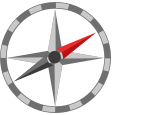**Magnetic field dip**

In this activity, you will compute the dip of the Earth's magnetic field in your location using your phone's magnetometer and the geometric definition of the dot product.

        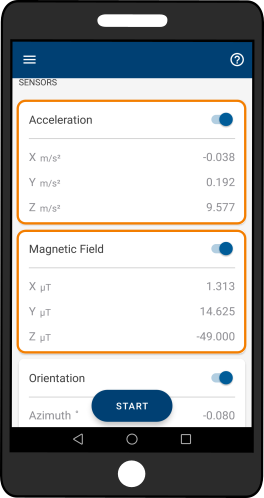

*Accelerometer and Magnetometer readings in the MATLAB Mobile app recorded in Natick, Massachusetts.*

  **Task. **Lay a cell phone flat and take an accelerometer and magnetometer reading from the MATLAB Mobile app. If you don't have a cell phone available, you can use the acceleration and magnetic field readings shown in the image above. Write them below as vectors $\mathbf{a}$ and $\mathbf{m}$.

a = [0 0 0]; % Default: [0 0 0] 
m = [0 0 0]; % Default: [0 0 0] 

% Plot the vectors
axisLims = [-60 60];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],a,"\mathbf{a}",10)
plotVector3D([0 0 0],m,"\mathbf{m}",10)
hold off
view([110 15])

As you can see from the plot, the magnetic field vector $\mathbf{m}$ doesn't point exactly north (if that was the case it would be in the $x$-$y$ plane) – in fact, in North America, much of it points into the Earth . You can compute the "dip angle" of the magnetic field using the geometric dot product.

  **Task. **

1. Compute the negative of the acceleration vector, $-\mathbf{a}$, to obtain the "down" vector, $\mathbf{d}$.

d = [0 0 0]; % Default: [0 0 0] 
checkd(d,a);

2. Compute the angle $\theta$ between $\mathbf{m}$ and "down", $\mathbf{d}$, using the geometric dot product solved for $\theta$: 

            
$$\theta = \cos^{-1} \left( \frac{ \mathbf{u} \cdot \mathbf{v} }{ \Vert \mathbf{u} \Vert  \Vert \mathbf{v} \Vert} \right)$$


theta = 0;
checkTheta(theta,d,m);

3. The angle commonly used to characterize the dip of the magnetic field is not the angle made with "down", but the angle made with the Earth's surface. This is known as the field's **inclination**. Compute this by subtracting $\theta$ from 90 degrees.

inclination = 0;
checkInclination(inclination,theta);

  **Reflect. **Check out this [wiki page](https://en.wikipedia.org/wiki/Magnetic_dip) that includes a[ map of the magnetic dips](https://upload.wikimedia.org/wikipedia/commons/d/de/World_Magnetic_Inclination_2015.pdf) around the globe. Does the value that you calculated for the inclination match the dip angle shown in the map for your location? 

## 4. Cross product

Unlike the dot product, which is defined for any N-dimensional vector, the cross product is typically only defined for 3D vectors. The cross product of $\mathbf{u} = [ u_1, u_2, u_3 ]$ and $\mathbf{v} = [v_1, v_2, v_3]$ is

    
$$\mathbf{u} \times \mathbf{v} = [ u_2 v_3 - u_3 v_2, \ u_3 v_1 - u_1 v_3, \ u_1v_2 - u_2v_1] $$
 

Notice that the cross product of two vectors is a vector, not a scalar.

** Exercise.** Compute the cross product of $\mathbf{u} = [1, 3, 6]$ and $\mathbf{v} = [1, 0, 2]$.

uCv = [0 0 0]; % Default: [0 0 0]
checkCrossProd(uCv) 

The cross-product vector points in a direction perpendicular to the first two vectors following the right-hand rule.

u = [0 0 0]; % Default: [0 0 0]
v = [0 0 0]; % Default: [0 0 0]
ucv = cross(u,v);
% Plot the vectors
axisLims = [-5 5];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims, axisLims, axisLims])
plotVector3D([0 0 0],u,"\mathbf{u}",1)
plotVector3D([0 0 0],v,"\mathbf{v}",1)
plotVector3D([0 0 0],ucv,"\mathbf{u \times v}",1)
hold off
view([110 15])

When determining which direction the vector $\mathbf{u} \times \mathbf{v}$ points, follow the *right-hand rule* by pointing the fingers of your right hand in the direction of the first vector $\mathbf{u}$, then rotate your fingers onto the second vector $\mathbf{v}$. Whichever direction your thumb points is the direction of $\mathbf{u} \times \mathbf{v}$. 

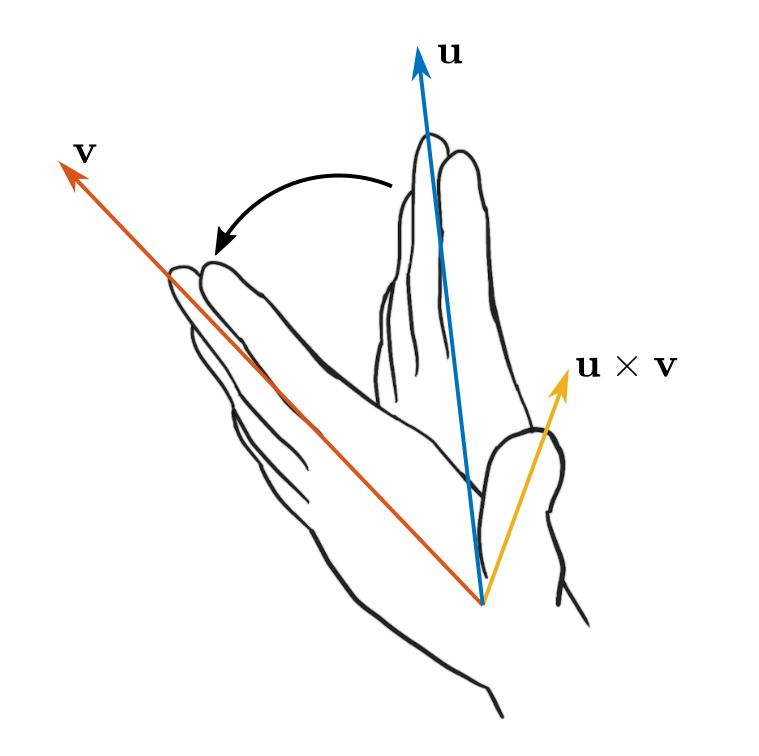

  **Reflect. **

- Consider vectors $\mathbf{u} = [3, 0, 0]$ and $\mathbf{v} = [0, 0, -5]$. Use the right-hand rule to determine the direction of $\mathbf{u} \times \mathbf{v}$.

- Set $\mathbf{u} = [3, 0, 0]$ and $\mathbf{v} = [0, 0, -5]$ above so that $\mathbf{u} \times \mathbf{v}$ is graphed. Did you get the direction right?

- Is the cross product commutative (i.e. does $\mathbf{u} \times \mathbf{v} = \mathbf{v} \times \mathbf{u}$)? If so, prove it using the definition. If not, what is the relationship between $\mathbf{u} \times \mathbf{v}$ and $\mathbf{v} \times \mathbf{u}$?

## 5. Magnetometer exploration

In this activity, you will take accelerometer and magnetometer readings, graph them as vectors, and use them together to find the orientation of the cell phone relative to north. Here are two ways you can access this type of data.

- Access the sensor data on your cell phone or tablet using the MATLAB Mobile app ([instructions](https://se.mathworks.com/help/matlabmobile/ug/sensor-data-collection-with-matlab-mobile.html)).

- Use the data in the attached video, [magnetometerReadings.mp4](matlab: winopen magnetometerReadings.mp4).

          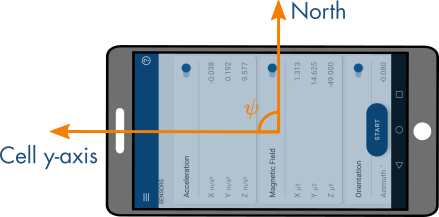

 In this exploration there is an assumption that the learner is in North America. In other regions, the activity may need to be adjusted to account for differences in the local geomagnetic field.

### Part 1

  **Task. **

- Open the MATLAB Mobile app and place the phone on a flat surface. Record the acceleration and magnetic field in `a` and `m`, respectively.

a = [0 0 0]; % Default: [0 0 0]
m = [0 0 0]; % Default: [0 0 0]

% Graph the accelerometer vector
axisLims = [-60 60];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],a,"\mathbf{a}",-5)
plotVector3D([0 0 0],m,"\mathbf{m}",-5)
hold off
view([110 25])

### Part 2

In this activity, you are only concerned with the orientation of the vectors, not their magnitude. In order to properly visualize the orientations, you can **normalize **them by converting them to **unit vectors. **The unit vector in the direction of a vector $\mathbf{v}$ is $\hat{\mathbf{v}} = \mathbf{v}/\Vert \mathbf{v} \Vert$, and has length 1. Note that dividing a vector by a scalar works just like multiplying by a scalar: divide each element in $\mathbf{v}$ by the scalar.

 **Exercise.** Convert the acceleration and magnetic field vectors to unit vectors and record the result.

an = [0 0 0]; % Default: [0 0 0]
mn = [0 0 0]; % Default: [0 0 0]

checkNormalization(a,an)
checkNormalization(m,mn)

% Graph the accelerometer vector
axisLims = [-1.5 1.5];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],an,"\hat{\mathbf{a}}",-0.3)
plotVector3D([0 0 0],mn,"\hat{\mathbf{m}}",-0.3)
hold off
view([110 25])

### Part 3

In North America, the magnetometer readings generally point north but have a large dip angle. In order to find the vector that points north without the dip, you can use cross products.

 **Exercise.** 

- Compute the down vector, $\mathbf{d}$, that points in the direction opposite to the normalized acceleration vector $\hat{\mathbf{a}}$.

- Take the cross product of the normalized magnetic field vector and the down vector: $\mathbf{d} \times \hat{\mathbf{m}}$. 

- Normalize the result of the cross products so that the new vector also has length 1 and store the results in $\mathbf{e}$`.`

% Record your accelerometer values below 
d = [0 0 0]; % Default: [0 0 0]
dxm = [0 0 0]; % Default: [0 0 0]
e = [0 0 0]; % Default: [0 0 0]
checkd(d,an)
checkCrossProduct(d,mn,dxm)
checkNormalization(dxm,e)

% Graph the accelerometer vector
axisLims = [-1.2 1.2];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],d,"\mathbf{d}",-0.1)
plotVector3D([0 0 0],mn,"\hat{\mathbf{m}}",-0.1)
plotVector3D([0 0 0],e,"\mathbf{e}",-0.3)
hold off
view([110 25])

  **Reflect. **

- The magnetic field $\mathbf{m}$ points down and to the north. Determine the direction (i.e., north, south, east, or west) that $\mathbf{e}$ points using the right-hand rule.

- What cross product can you compute to find the vector that points north?

### Part 4

 **Exercise.** 

- Compute the cross product $\mathbf{e} \times \mathbf{d}$.

% Record your accelerometer values below 
n = [0 0 0]; % Default: [0 0 0]
checkCrossProduct(e,d,n)
% Graph the accelerometer vector
axisLims = [-1.2 1.2];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],d,"\mathbf{d}",-0.3)
plotVector3D([0 0 0],e,"\mathbf{e}",-0.3)
plotVector3D([0 0 0],n,"\mathbf{n}",-0.3)
hold off
view([110 25])

  **Reflect. **

- As you probably surmised, the vector $\mathbf{e}$ points east and $\mathbf{n}$ points north. In this configuration, the yaw of the phone is the angle $\psi$ that $\mathbf{n}$ makes with the $y$-axis. How can you estimate this angle?

### Part 5

 **Exercise.** 

- You can use the geometric definition of the dot product to estimate the heading relative to north, $\psi$. To do so, compute the angle (in degrees) between the vector $\mathbf{u} = [0,1,0]$ that points in the direction of the $y$-axis and the vector $\mathbf{n}$.

psi = 0; % Default: [0 0 0]
checkAngleBetweenVectors([0 1 0],n,psi)

  **Reflect. **

- The angle $\psi$ that you measured is the yaw (or, in the MATLAB Mobile app, the azimuth). Point your phone in the same direction that you took the reading in and look at the azimuth recorded in the sensors menu of the app. Does it match the angle $\psi$ that you computed?

### **Further exploration**

If you were to adjust the pitch or roll of the phone, would the computation from Part 5 still give the yaw angle?

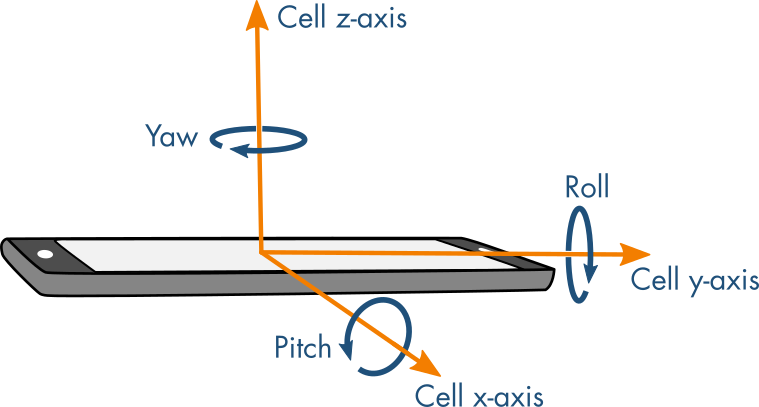

            *Illustration of the cell phone axes and rotation*

   Try positioning your phone in the same orientation as before but with the phone lifted so that the pitch angle is increased and record the vector values below. The angle $\psi$ is computed in the same way as before and shown below.

% Record your accelerometer values below vc
a = [0 0 0]; % Default: [0 0 0]
m = [0 0 0]; % Default: [0 0 0]
an = a/norm(a);
mn = m/norm(m);
d = -an;
e = cross(d,mn); 
e = e/norm(e);
n = cross(e,d);

% Graph the accelerometer vector
axisLims = [-1.2 1.2];
figure("position",[1 1 400 400])
hold on
plotVector3DAxis([axisLims axisLims axisLims])
plotVector3D([0 0 0],an,"\hat{\mathbf{a}}",-0.2)
plotVector3D([0 0 0],mn,"\hat{\mathbf{m}}",-0.2)
plotVector3D([0 0 0],e,"\mathbf{e}",-0.3)
plotVector3D([0 0 0],n,"\mathbf{n}",-0.3)
hold off
view([110 25])
u = [0 1 0];
psi = acosd(dot(n,u)./(norm(n)*norm(u)))

You should see that $\psi$ has changed due to the pitch change. This means the angle $\psi$ calculated above is no longer the yaw (because the phone is not lying flat).

 [Challenge problem] Can you come up with a way to compute the angle $\psi$ so that it accurately captures the yaw when the phone is tilted?

%% Helper functions
%% Plotting functions: these are used to visualize vectors

function setup2DVectorPlot(axisLims) 
% Set up axes for visualizing 2D vectors
    fs = 14; 
    ax = gca;
    ax.XAxisLocation = "origin";
    ax.YAxisLocation = "origin";    
    ax.Position = [0.05, 0.05, 0.9, 0.9];
    axis equal tight
    axis(axisLims)
    box on
    xlabel("$x$","Interpreter","latex","fontsize",fs)
    ylabel("$y$","Interpreter","latex","fontsize",fs)
    ax.XTick = round(axisLims(1)) : round(axisLims(2));
    ax.XTickLabel = [];
    ax.YTick = round(axisLims(1)) : round(axisLims(2));
    ax.YTickLabel = [];
end

function plotVector2D(u0,u,name,nameOffset) 
% Visualizes a 2D vector with the given name
    fs = 14; 
    quiver(u0(1),u0(2),u(1),u(2),"autoscale","off","maxheadsize",1/norm(u),"linewidth",1.5)
    offset = null(u)/3*nameOffset;
    text(u0(1) + u(1)/2 + offset(1), u0(2) + u(2)/2 + offset(2), strcat("$",name,"$"), ...
        "Interpreter","latex","fontsize",fs,"HorizontalAlignment","center")
end

%% These functions are for plotting 3D vectors with their labels
function plotVector3DAxis(axlims) 
    % Sets up nice axes for visualizing 3D vectors
    cla
    fs = 14; 
    lb = axlims(1);
    ub = axlims(2);
    a = lb;
    b = ub-a;
    buff = b*0.1;
    c = ub+buff/2;
    ca = [0.3 0.3 0.3 0.6];
    axis([a-buff,c+buff,a-buff,c+buff,a-buff,c+buff])
    quiver3(a,0,0,b,0,0,"autoscale","off","maxheadsize",1/10,"linewidth",1,"color",ca)
    quiver3(0,a,0,0,b,0,"autoscale","off","maxheadsize",1/10,"linewidth",1,"color",ca)
    quiver3(0,0,a,0,0,b,"autoscale","off","maxheadsize",1/10,"linewidth",1,"color",ca)
    text(c,0,0,"$x$", "Interpreter","latex","fontsize",fs)
    text(0,c,0,"$y$", "Interpreter","latex","fontsize",fs)
    text(0,0,c,"$z$", "Interpreter","latex","fontsize",fs)
    axis equal tight
    set(gca,"Position",[0.05 0.05 0.9 0.9],"CameraViewAngleMode","Manual",...
        "Color","none","XColor","none","YColor","none","ZColor","none","ColorOrderIndex",1)
end

function plotVector3D(u0,u,name,nameOffset) 
% Visualizes a 3D vector with the given name
    fs = 14; 
    xlims = 0.5*get(gca,"xlim");
    scaleFactor = 0.25*(xlims(2) - xlims(1));
    quiver3(u0(1),u0(2),u0(3),u(1),u(2),u(3),"autoscale","off","maxheadsize",scaleFactor/norm(u),"linewidth",1.5)
    if(any(u))
        offset = null(u)/3*nameOffset;
    else
        offset=[0 0 0];
    end
    text(u0(1) + u(1)/2 + offset(1), u0(2) + u(2)/2 + offset(2), u0(3) + u(3)/2 + offset(3),...
        strcat("$",name,"$"), "Interpreter","latex","fontsize",fs,"HorizontalAlignment","center")
end

%% These functions check the answers to exercises in the script
function checkAns(val,userVal) % Checks the answer of a variable
    if(all( abs( userVal - val ) < 1e-3 ))
        disp("Correct!")
    else
        warning("Incorrect :(")
    end
end

function checkAddition(userVal)
    val = [4 -3 12];
    checkAns(val,userVal);
end

function checkSubtraction(userVal) 
    val = [-2 9 12];
    checkAns(val,userVal);
end

function gradeC(a,b,c)
    checkAns(b-a,c);
end

function checkScalarMult(userVal)
    val = [0.5 2 -2];
    checkAns(val,userVal);
end

function checkDotProduct(userVal) 
    val = 13;
    checkAns(val,userVal);
end

function checkGeometricDot(userVal) 
    val = 4;
    checkAns(val,userVal);
end

function checkAngleBetween(userVal)
    u = [-1 3 2];
    v = [2 4 -1];
    val = acosd(dot(u,v)./(norm(u)*norm(v)));
    checkAns(val,userVal);
end

function checkd(d,a)
    checkAns(-a,d);
end

function checkTheta(theta,d,m)
    val = acosd(dot(d,m)./(norm(d)*norm(m)));
    checkAns(theta,val);
end

function checkInclination(inclination,theta)
    checkAns(90-theta,inclination)
end

function checkCrossProd(userVal) 
    val = [6 4 -3];
    checkAns (val,userVal);
end

function checkCrossProduct(u,v,userVal)
    checkAns(cross(u,v),userVal)
end

function checkAngleBetweenVectors(u,v,userVal)
    val = acosd(dot(u,v)./(norm(u)*norm(v)));
    checkAns(val,userVal);
end

function checkNormalization(v,userVal)
    checkAns(v./norm(v),userVal)
end

% Suppress unused suggestions
%#ok<*UNRCH> 